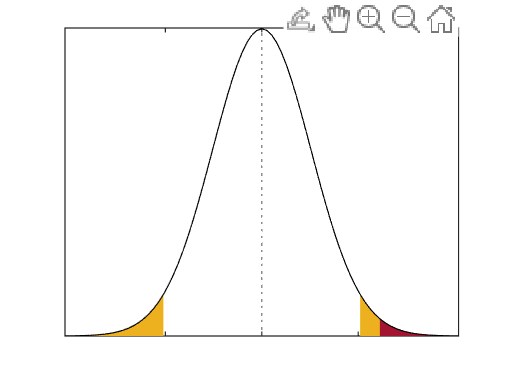

x = -4:.1:4;
y = normpdf(x,0,1);
xValue = 1.96;
tValue = 2.4;
[~,idxP] = min(abs(x - xValue));
[~,idxN] = min(abs(x + xValue));
[~,idxT] = min(abs(x - tValue));
plot(x,y,'k'); xticks([-xValue 0 xValue]);yticks([]);xticklabels({'','',''})
hold on;
area(x(idxP:end),y(idxP:end),"FaceColor",'#EDB120');
area(x(1:idxN),y(1:idxN),"FaceColor",'#EDB120');
area(x(idxT:end),y(idxT:end),"FaceColor",'#A2142F');
hold off
xline(0,':');

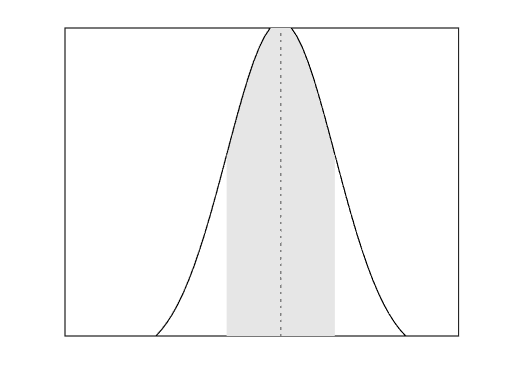

x = -4:.1:4;
y = normpdf(x,0,1);
xValue = 1;
[~,idxP] = min(abs(x - xValue));
[~,idxN] = min(abs(x + xValue));
plot(x,y,'k'); xticks([]);yticks([]); xticklabels({'',''})
hold on;
area(x(idxN:idxP),y(idxN:idxP),"FaceColor",[.9 .9 .9]);
hold off
xline(0,':');

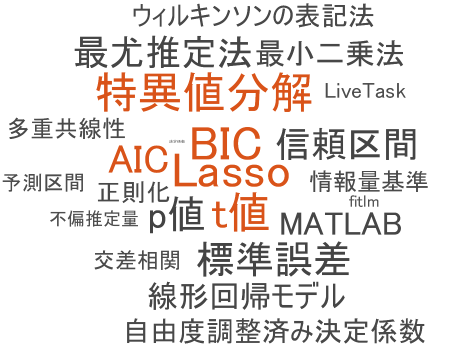

myText = ["信頼区間", "予測区間", "LiveTask", "線形回帰モデル", "ウィルキンソンの表記法", "最小二乗法", "最尤推定法", "不偏推定量","fitlm", ...
"決定係数","自由度調整済み決定係数","AIC","情報量基準","標準誤差","p値","t値","特異値分解","多重共線性","交差相関","MATLAB","正則化","Lasso","BIC"];
wordcloud(myText,abs(randn(length(myText),1)+4.5))